## WirelessNetwork Documentation -- Example #1

The purpose of this Live Editor document is to provide a first example of a complete wireless network that is representative of what you will need to turn in for your preliminary design.  This example does not use sectorization (see example #2 for that).

It is assumed that you have worked through the first two documents that describe how to create and use a `WirelelessNetwork` object, but you don't need to go through the third document on sectorization (which is covered in the second example).

# Creating a WirelessNetwork Object

We begin by creating a `WirelessNetwork` object and assign it to `net`, which is the name of the variable that describes our network.  To do this, type the following:

net = WirelessNetwork

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: []
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


# Managing Channels

The next step is to group the chanels that you purchased into "`channel_sets`".   The vector called `channel_sets` specifies how many channels are in a particular set.  This is important because cells are assigned channel sets rather than individual channels.  Later, when we create our base stations, we will need to indicate which channel set to associate with the base station.

Suppose that we have purchased the licenses to 30 RF channels.  Moreover, suppose that we do not plan to use sectorization (see the other example for sectorization) and that we would like to have 4 channel sets (think of this as clusters of size N=4).   Because 30/4 is not an integer, we cannot assign the same number of channels to each channel set.  Instead, we could have 2 channel sets that each contain 7 channels and 2 channel sets that each contain 8 channels, since 2*7+2*8 = 30.

We can specify our channel sets as a vector containing two 7's and two 8's.  We can order those numbers however we like, for instance:

net.channel_sets = [7 7 8 8]

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: [7 7 8 8]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


As a sanity check, please verify that the total number of channels in the channel set does not exceeed the number of channels you are willing to purchasing (keeping in the mind the cost to license each channel):

total_channels = sum(net.channel_sets)

total_channels = 30

# Estimating the Number of Base Stations (EDIT)

Before we start placing our base stations, we need to estimate how many we can afford.  As described in WirelessProjectPart1.mlx, each base station has a fixed cost of $250,000 (meant to include the cost of the property it is located on, the tower struture, and the networking/power resources provided to it) plus $25,000 per RF channel's transciever (meant to be the cost of the radio equipment).   Because our channel sets do not have the same number of chanels in them (there can be either 7 or 8 channels assigned to a cell), the costs will vary.  The cheapest base station will be 250+7*25 = $425,000, which is when 7 channels are used.  The most expensive base station is 250+8*25 = $450,000, which is when 8 channels are used.  Since we have just as many channel sets with 7 channels as we have with 8 channels, $437,500 is the average cost of a base station.   

Suppose our total budget is $30,000,000.  We have licensed 30 RF channels, which cost $500,000 each.  Thus the cost of our spectrum licenses is 30*500 = $15,000,000.  Given our overall budget, this leaves $15,000,000 for base stations.  We can afford 15000/437.5 = 34.29 of the "average" base stations, but we need to round down to 34 or else we will exceed our budget if we have a roughly equal number of both kinds of base stations (we could afford 34 base stations if we use 12 of the $425K stations and 22 of the $450K stations).   If we randomly assign channel sets to base stations, then we need to be careful not to exceed the budget.

# Adding a Single Base Station

While you could use the C`reateCentralCluster` or `CreateFirstTier` methods to lay out a regular hexagonal network, such an approach has several limitations that make them unsuitable for your network.  First, using those methods implies using a certain number of base stations that might not be well matched to your budget.  For instance, recall that for the N=4 cluster size, `CreateFirstTier` creates a network containing 28 base stations.  Similarly, for our N=3 network, `CreateFirstTier` will create a network containing 21 base stations.  Neither of those functions will be able to create a network for us containing exactly 34 base stations.

Furthermore, hexagonal networks are homogenous networks meant to provide even coverage over the areas they are located.  They are not particularly well suited for networks with an uneven (non-homogenous) population of users, such as in Morgantown.  ***For your network, you will likely want to depart from using a hexagonal network and instead customize the geometry of your network to be better matched to where your users are located.***

So we will instead lay out our network by calling the `AddBase` method.  We can call the method once for each base station we want to place, or alternatively we can determine all of the locations and call `AddBase` once (by providing it with vector arguments).

To begin, let's create a single base station.  We first need to give it a location, and for this example we will locate it randomly (in your final design, they should not be purely random like this).   Recall that the map of Morgantown extends from coordinate 0 to coordinate 600 in each direction.  Recall also that we need to use complex numbers to specify locations in our network (the real part of the number is our east-west coordinate and the imaginary part of the number is our north-south coordinate).   In MATLAB, `rand` gives a random number that is uniformly distributed from 0 to 1, so it follows that 600*rand will be uniform from 0 to 600.  Thus, we can get a random location by setting each of the real and imaginary components to be uniform from 0 to 600:

location = 600*rand+1i*600*rand

location = 3.9329e+02 + 1.0271e+02i

Next, we need to assign channel sets to the cell.  Since we were not using sectorization, then the channel set is a single integer value that specifies which channel set the whole cell uses.  To pick channel sets randomly, we could use MATLAB's `randi` function, which draws random integers.  If we want to pick from the integers 1 through 4, we can call it as follows:

channels = randi(4)

channels = 3

This assignment is random.  Since half of the channel sets have 7 channels and half have 8 channels, the cost of the base station will also be random.

Next, we need to specify the transmit power of the base station.  When sectorization is not being used, it is a single value.  Your transmit powers should not exceed 40 dBm.  For this example, let's pick a random value between 30 and 40 dBm by using the `rand `function (for your final design these should not be purely random):

power_dBm = 30+10*rand

power_dBm = 30.3183

We now have what we need to create our base station, and can do so by using the `AddBase` method:


net.AddBase( location, channels, power_dBm );

We now have a network with a single base station, but before we move on, let's remove it:

net.RemoveBase(1);

# Adding Multiple Base Stations

We would like to create a network containing 34 base stations that are each generated randomly like the first one.  We can do this in a loop that we go through 34 times, as follows:

for i=1:34
    location = 600*rand+1i*600*rand;
    channels = randi(4);
    power_dBm = 30+10*rand;
    net.AddBase( location, channels, power_dBm );
end

Let's look at the net object to verify that it has 34 base stations:

net

net =   WirelessNetwork with properties:

           bs_locations: [34×1 double]
            bs_channels: [34×1 double]
           bs_power_dBm: [34×1 double]
           channel_sets: [7 7 8 8]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


# Analyzing the Network

Let's confirm the cost of the network:

net.ComputeCost

ans = 29775

Due to the random selection of channel sets, it is possible that we have exceeded our budget.

Now let's generate some maps to show what this looks like.  Begin with a coverage map, making sure to increase the map resolution before drawing it:

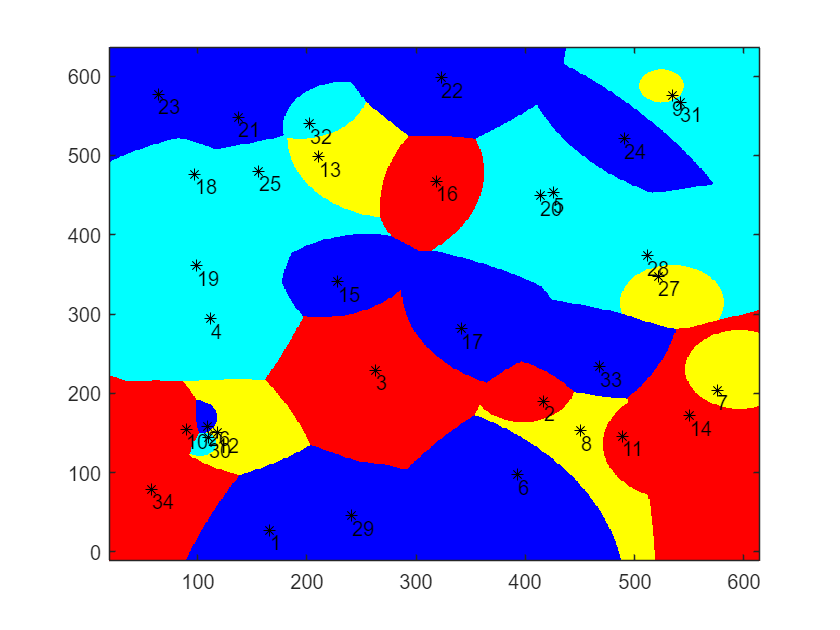

net.map_resolution = 600;
net.MapCoverage;

Next, map the SINR outage regions:

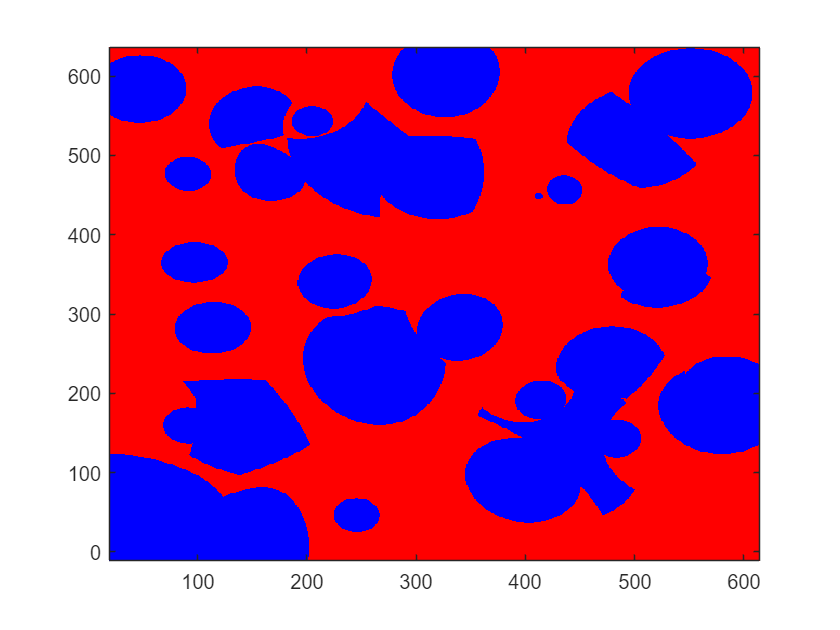

Covering 41.98 percent of the area with sufficient SINR
worst case SINR is -3.433739


net.MapSINR

Recall that this map shows you the regions where the SINR is below the threshold (in red).

Now, let's look at what our network looks like on a city map of Morgantown:

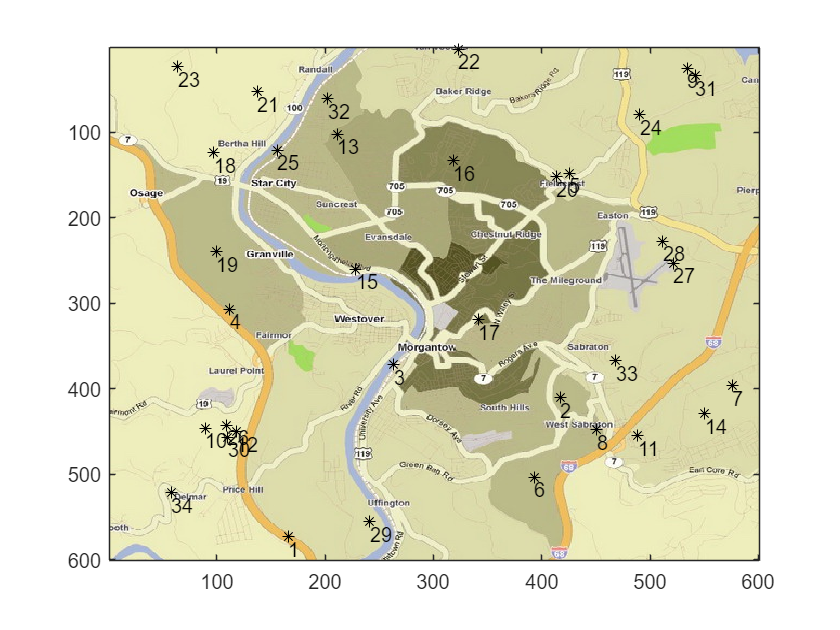

ans = struct with fields:
       cdata: [514×652×3 uint8]
    colormap: []


net.MapCity

Next, let's put mobiles onto the map.  Load the data file containing locations of our mobiles, and show them at the busiest hour (19:00):

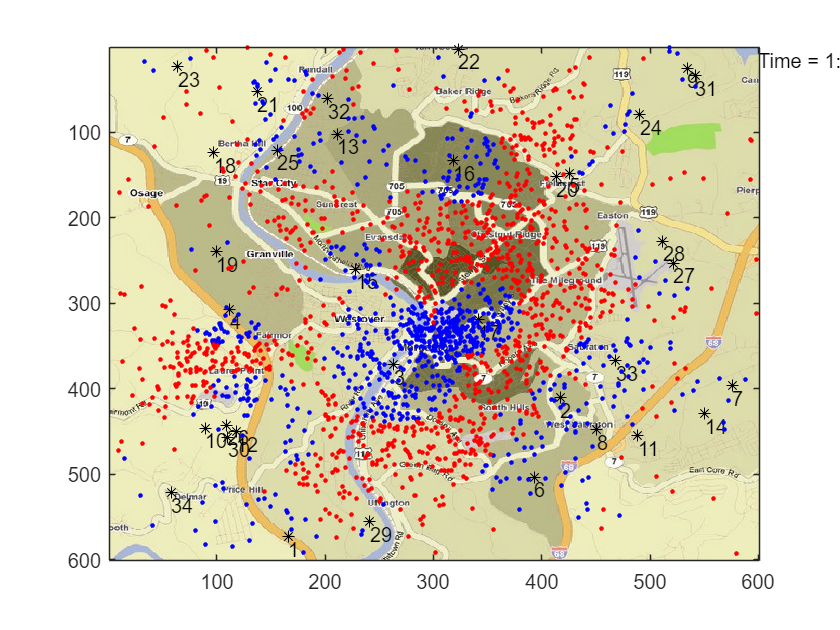

load( 'MobileLocationData' );
net.MapCity( ms_locations{19} );

Now let's put the mobiles onto our coverage map:

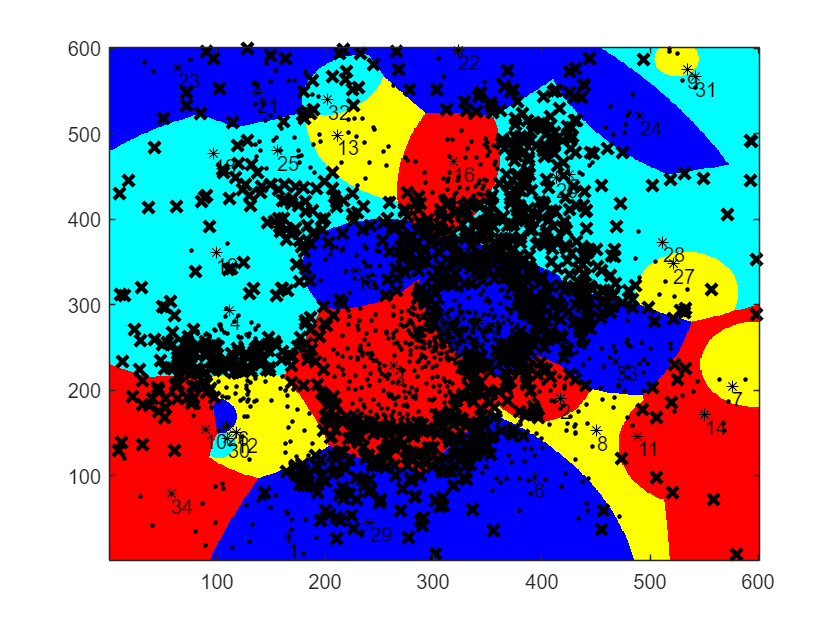

ans = struct with fields:
       cdata: [514×652×3 uint8]
    colormap: []


% show the mobiles at 19:00 on the coverage map
net.MapMobiles( ms_locations{19} )

Net, let's analyze the performance:

[num_connected, num_over_thresh] = net.AnalyzeNetwork( ms_locations )

num_connected =    204   165   134    77   104   196   241   330   414   379   379   476   489   418   411   454   506   503   551   510   472   405   353   302


num_over_thresh =    204   165   134    77   104   196   250   388   538   469   469   685   717   582   570   618   748   751   847   775   679   519   432   326


Plot the total number of connected users, the number of call attempts, and the number over threshold (i.e., the number that are *covered*) on the same plot:

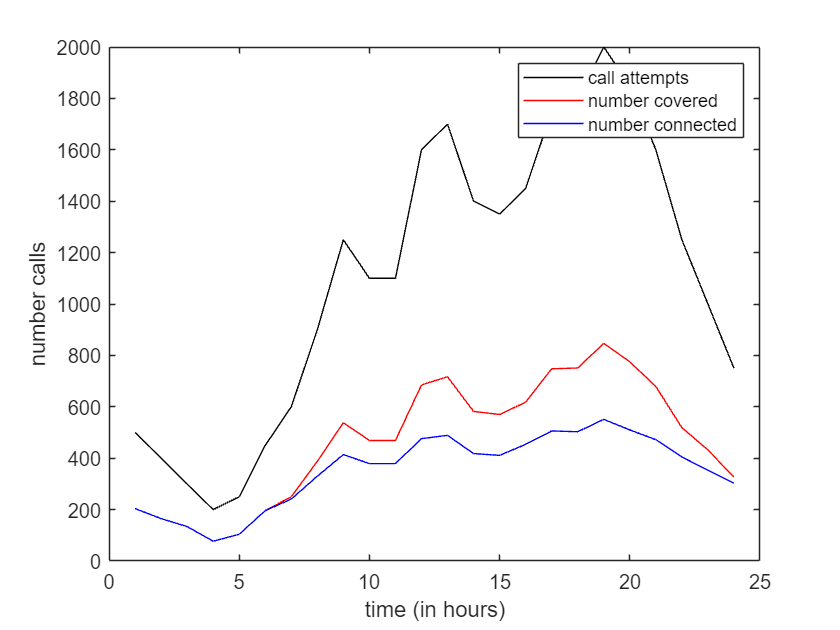

plot( 1:length(call_attempts), call_attempts, '-k', ...
    1:length(call_attempts), num_over_thresh, '-r', ...
    1:length(call_attempts), num_connected, '-b' );
xlabel( 'time (in hours)' );
ylabel( 'number calls' );
legend( 'call attempts', 'number covered', 'number connected' );

You may need to move the figure's legend so that it does not cover a curve.

Alternatively, we could plot the *fraction* of users that are covered and the fraction that are covered and connected:

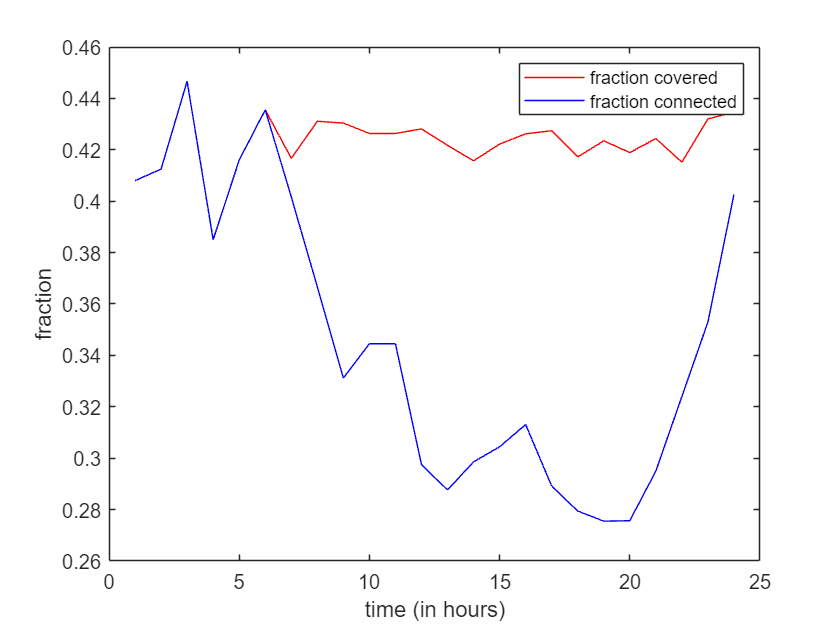

fraction_over_thresh = num_over_thresh./call_attempts;
fraction_connected = num_connected./call_attempts;
plot( 1:length(call_attempts), fraction_over_thresh, '-r', ...
    1:length(call_attempts), fraction_connected, '-b');
xlabel( 'time (in hours)' );
ylabel( 'fraction' );
legend( 'fraction covered', 'fraction connected');

If we want a single KPI (key performance indicator), it is the total number of connected users throughout the day:

sum(num_connected)

ans = 8473

The goal should be for this value to be close to the number of call attempts for the day

sum( call_attempts )

ans = 26550

The percentage of users that are connected can be echoed to the screen using:

percent_connected = sum(num_connected)/sum(call_attempts);
fprintf( 'The percentage connected is %2.2f%%\n', 100*percent_connected)

The percentage connected is 31.91%


# Saving the Network

Save your file using a name like PreliminaryDesign.mat

net.Save( "Preliminary.mat")
